# クラシック音楽の作曲家分類

Copyright 2020 Michio Inoue

## 基本方針

- 前処理済み（`DivideTrainFiles.mlx`, `DivideTestFiles.mlx`）を想定

- 学習量音源は各ファイルから 20 秒分 最大 8 つ切り出したものを使用

- ただ、データ量が少ない 'grieg' （8ファイル）は各ファイル最大 128 個まで、 'wagner' (14ファイル)は各ファイル最大 73 個（128/14*8）までとする。

- テスト量音源については単純に冒頭から 20 秒づつ分割したものを使用して、最終的な予測結果はそれぞれの予測結果の多数決をとる。

### 使用したツール

- MATLAB R2020b

- Audio Toolbox

- Signal Processing Toolbox

- Machine Learning and Statistics Toolbox

- Parallel Computing Toolbox (Recommended)

### 手法

サンプルプログラム：[Music Genre Classification Using Wavelet Time Scattering](https://jp.mathworks.com/help/wavelet/ug/music-genre-classification-using-wavelet-scattering.html) と同じ手法を使用します。ほぼそのままなので詳細はリンク先を確認ください。

#### サンプルプログラムについてまとめ

- ジャズやクラシックなど10種類のジャンル分類をする課題

- 音源は30秒間のファイル

- 特徴量は Walet Scattering 係数（冒頭の 約 23 秒間だけ使用）

- 機械学習は SVM を使用

- 1つの音源から複数の特徴量を計算、それぞれ分類。最終的なラベルは多数決で決定。

#### このコードでの変更点

- 音源の長さは様々なので、それぞれのファイルから 20 秒間だけ切り出したものを使用（簡単のため）

- 特徴量は例題通り（簡単のため）

- 機械学習には kNN を使用（簡単のため）

- kNN のハイパーパラメータは一部のデータを使用したベイズ最適化で求めた（distance = cityblock, numNeighbors = 1）

clear

ディレクトリ情報の確保

settings = jsondecode(fileread('..\settings.json'))

settings = フィールドをもつ struct :
           RAW_DATA_DIR: '../data/'
     PROCESSED_DATA_DIR: '../data/processed/'
    TRAIN_PROCESSED_DIR: '../data/processed/train'
     TEST_PROCESSED_DIR: '../data/processed/test'
              MODEL_DIR: '../models/'
         SUBMISSION_DIR: '../submissions/'


## モデル学習

TrainFeatures と TestFeatures を使って[分類学習器](https://jp.mathworks.com/help/stats/classification-learner-app.html)アプリで適当なアルゴリズムをベイズ最適化によって決定。

ここでは比較的精度も良く学習時間も短い最近傍法 (k=1) で距離尺度は cityblock を使用します。

計算時間を短縮するため PCA で 95% の分散を説明することができる主成分数に絞ります。

詳細はアプリから自動生成した trainClassifier.m を確認。

trainFeaturesFilename = fullfile(settings.PROCESSED_DATA_DIR, 'trainFeatures.mat');
load(trainFeaturesFilename,'TrainFeatures','trainLabels','TestFeatures','testLabels','adsTest');
trainingData = TrainFeatures;
responseData = trainLabels;

trainedClassifier = trainClassifier(trainingData, responseData);

## 精度検証

検証用データを使って予測結果を確認します。まずは 773 x 16 = 12368 個の結果（個別の特徴量に対する結果）。

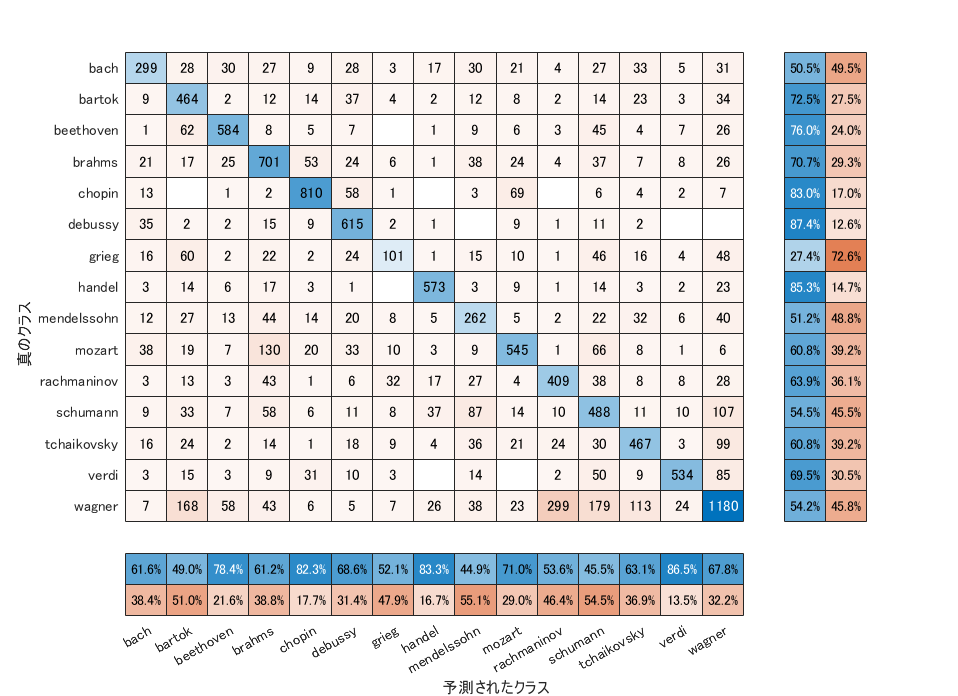

predLabels = trainedClassifier.predictFcn(TestFeatures);
f = figure(1);
f.Position = [149.8000  204.2000  766.4000  556.8000];
confusionchart(testLabels,predLabels,...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');

### 多数決

1つのファイルから 16 セットの特徴量を作っているので、16個の予測結果から多数決をもって最終的なラベルを求めます。詳細は `helperMajorityVote.m` を確認。[ウェーブレット時間散乱を使用した音楽ジャンルの分類](https://jp.mathworks.com/help/signal/examples/music-genre-classification-using-wavelet-scattering.html)で使われている `helperMajorityVote.m` は同じ得票数のラベルがあった場合には `NoUniqueMode` という結果を返すが、この部分は使用しない（必ず何らかの結果を返す）

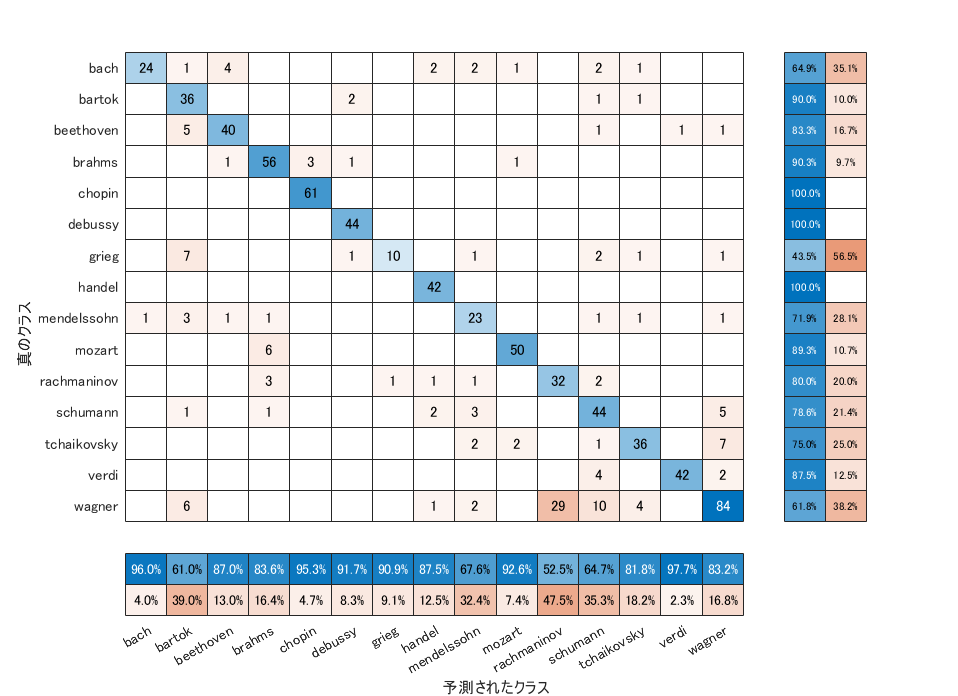

classes = categorical(trainedClassifier.ClassificationKNN.ClassNames);
[TestVotes,TestCounts] = helperMajorityVote(predLabels,adsTest.Labels,classes);


f = figure(2);
f.Position = [149.8000  204.2000  766.4000  556.8000];
confusionchart(categorical(adsTest.Labels),TestVotes,...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');

wagner, grieg などデータ数が少ないラベルの予測精度がいまいちな傾向にあります。

## テストデータ（提出用）の予測

学習データ＋検証用データで再学習したのち、テスト用データ（提出用）の予測を同様におこないます。

trainingData = [TrainFeatures; TestFeatures];
responseData = [trainLabels; testLabels];

trainedClassifier = trainClassifier(trainingData, responseData);
modelFilename = fullfile(settings.MODEL_DIR,'modelknn.mat');
save(modelFilename,'trainedClassifier');